clear;clc;close all;

editionNames={'Paris (2024)','Tokyo (2021)','Rio (2016)','Total (2016-2024)'};
confMat(:,:,1)=[227,22;18,63];
confMat(:,:,2)=[228,30;22,64];
confMat(:,:,3)=[215,47;23,85];

figure;hold on;grid on;axis equal;axis([0.6 0.8 0.6 0.8]);
set(gca,'FontName','メイリオ');
for n1=1:size(confMat,3)
    Y=ones(sum(confMat(:,:,n1),'all'),1);
    % レーティングによる予測正解
    YHat1=[ones(confMat(1,1,n1),1);
        ones(confMat(1,2,n1),1);
        zeros(confMat(2,1,n1),1);
        zeros(confMat(2,2,n1),1);];
    % ランキングによる予測正解
    YHat2=[ones(confMat(1,1,n1),1);
        zeros(confMat(1,2,n1),1);
        ones(confMat(2,1,n1),1);
        zeros(confMat(2,2,n1),1);];
    [h,p,e1,e2]=testcholdout(YHat1, YHat2, Y)

    scatter(mean(YHat1),mean(YHat2),'LineWidth',2);
    text(mean(YHat1),mean(YHat2),['　p=' num2str(p,'%1.2e')],'fontname','メイリオ');
end

h = logical
   0


p = 0.5327

e1 = 0.2455

e2 = 0.2576

h = logical
   0


p = 0.2717

e1 = 0.2500

e2 = 0.2733

h = logical
   1


p = 0.0041

e1 = 0.2919

e2 = 0.3568


%3大会合計
Y=ones(sum(confMat(:,:,:),'all'),1);
% レーティングによる予測正解
YHat1=[ones(sum(confMat(1,1,:)),1);
    ones(sum(confMat(1,2,:)),1);
    zeros(sum(confMat(2,1,:)),1);
    zeros(sum(confMat(2,2,:)),1);];
% ランキングによる予測正解
YHat2=[ones(sum(confMat(1,1,:)),1);
    zeros(sum(confMat(1,2,:)),1);
    ones(sum(confMat(2,1,:)),1);
    zeros(sum(confMat(2,2,:)),1);];
[h,p,e1,e2]=testcholdout(YHat1, YHat2, Y)

h = logical
   1


p = 0.0047

e1 = 0.2634

e2 = 0.2979

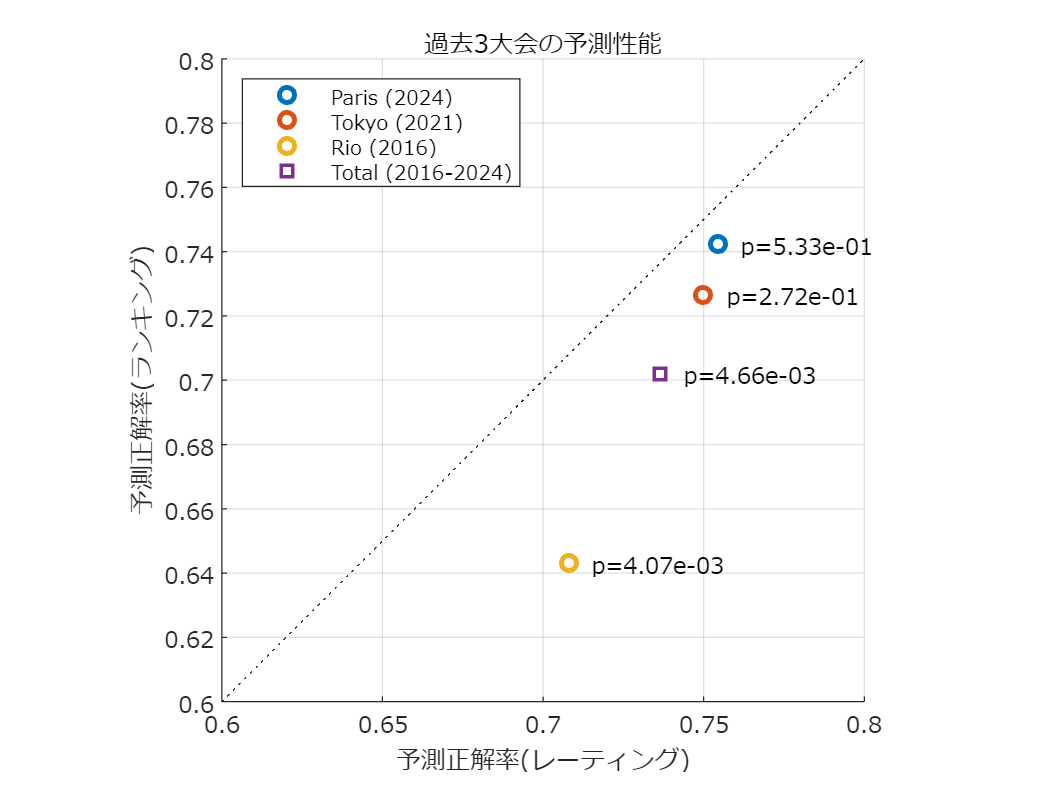


scatter(mean(YHat1),mean(YHat2),'s','LineWidth',2);
text(mean(YHat1),mean(YHat2),['　p=' num2str(p,'%1.2e')],'fontname','メイリオ');

xlabel('予測正解率(レーティング)');ylabel('予測正解率(ランキング)');
title('過去3大会の予測性能');
plot([0.6 0.8],[0.6 0.8],'k:');
legend(editionNames,'Location','northwest');
exportgraphics(gcf,'fig_predictionPerformanceHistory.pdf');